# Bamboo Chair Loadcase Classification (ME 780 DA3)

Trains a pattern-recognition neural network (patternnet, one hidden layer of 10 neurons) to classify the loadcase acting on a bamboo chair from the maximum applied load and the x/y positions of three tracked points, then evaluates it on the training data and on two loadcases it never saw in training.

## Load Data

Load the training and test data sets.

trainData = readtable('trainData.xlsx');

testData = readtable('testData.xlsx');

Inspect the training data

%plot(feat);
size(trainData.Category)

ans =    200     1


head(trainData)

ans = 8×8 table
        Category        MaximumLoadApplied    Load_Application_Point_x    Load_Application_Point_y    Backrest_Armrest_Junction_x    Backrest_Armrest_Junction_y    Armrest_x    Armrest_y
    ________________    __________________    ________________________    ________________________    ___________________________    ___________________________    _________    _________

    {'45kg_Sitting'}          45.617                       10                          38                           34                             44                    28           22  
    {'45kg_Sitting'}          43.256                   9.4824                      36.033                        32.24                         41.723 

**Create neural network for pattern recognition**

net = patternnet

net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 10
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      in

Examine layers, weights, bias values

view(net)
net.layers{1}

ans =     Neural Network Layer
 
              name: 'Hidden'
        dimensions: 10
       distanceFcn: (none)
     distanceParam: (none)
         distances: []
           initFcn: 'initnw'
       netInputFcn: 'netsum'
     netInputParam: (none)
         positions: []
             range: [10x2 double]
              size: 10
       

net.layers{2}

ans =     Neural Network Layer
 
              name: 'Output'
        dimensions: 0
       distanceFcn: (none)
     distanceParam: (none)
         distances: []
           initFcn: 'initnw'
       netInputFcn: 'netsum'
     netInputParam: (none)
         positions: []
             range: []
              size: 0
       

lweights = net.LW

lweights = 2×2 cell array
    {0×0  double}    {0×0 double}
    {0×10 double}    {0×0 double}


biases = net.b

biases = 2×1 cell array
    {10×1 double}
    { 0×1 double}


Specify division of data for training, validation, and testing

%net.divideParam.trainRatio = 70/100;
%net.divideParam.valRatio = 15/100;
%net.divideParam.testRatio = 15/100;
net.trainParam.epochs = 2000;
net.performParam.regularization =0.01;

## Prepare Data

Extract numeric predictor data from the tables and transpose.

xTrain = trainData{:,vartype("numeric")}';
xTest = testData{:, vartype("numeric")}';

Convert the loadcase labels to numeric matrices and transpose

train_state = categorical(trainData.Category);
yTrain = dummyvar(train_state)'

yTrain =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

test_state = categorical(testData.Category);
yTest = dummyvar(test_state)'

yTest =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


labels = categories(train_state)

labels = 4×1 cell array
    {'14kg_Leaning'}
    {'19kg_Leaning'}
    {'45kg_Sitting'}
    {'72kg_Sitting'}


**Train Network**

net = train(net, xTrain, yTrain);

## Examine network parameters

view(net)
net.layers{1}

ans =     Neural Network Layer
 
              name: 'Hidden'
        dimensions: 10
       distanceFcn: (none)
     distanceParam: (none)
         distances: []
           initFcn: 'initnw'
       netInputFcn: 'netsum'
     netInputParam: (none)
         positions: []
             range: [10x2 double]
              size: 10
       

net.layers{2}

ans =     Neural Network Layer
 
              name: 'Output'
        dimensions: 4
       distanceFcn: (none)
     distanceParam: (none)
         distances: []
           initFcn: 'initnw'
       netInputFcn: 'netsum'
     netInputParam: (none)
         positions: []
             range: [4x2 double]
              size: 4
       

## Evaluate network

scores = net(xTest)

scores =     0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0093    0.0088    0.0114    0.0116    0.0115    0.0115    0.0115    0.0105    0.0112    0.0119    0.0117    0.0118    0.0111    0.0087    0.0107    0.0106    0.0116    0.0095    0.0115    0.0120    0.0110    0.0118    0.0102    0.0113    0.0117    0.0105    0.0080    0.0065    0.0092    0.0106    0.0062    0.0095    0.0117    0.0094    0.0085    0.0072    0.0119    0.0104    0.0084    0.0101    0.0095    0.0117    0.0109    0.0073    0.0111    0.0118    0.0119    0.0088    0.0099

scoresTrain = net(xTrain)

scoresTrain =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0027    0.0020    0.0023    0.0019    0.0034    0.0021    0.0021    0.0024    0.0030    0.0023    0.0022    0.0022    0.0029    0.0025    0.0028    0.0023    0.0021    0.0021    0.0020    0.0019    0.0021    0.0024    0.0024    0.0021    0.0023    0.0025    0.0020    0.0023    0.0020    0.0020    0.0021    0.0022    0.0023    0.0022    0.0023    0.0021    0.0029    0.0033    0.0024    0.0018    0.0019    0.0023    0.0020    0.0026    0.0024    0.0023    0.0021    0.0021    0

Convert scores to original format for easier completion

[~, yNum] = max(scores);
[~, yNumTrain] = max(scoresTrain);
yPred = categorical(yNum, 1:4, labels)';
yPredTrain = categorical(yNumTrain, 1:4, labels)';

Evaluate classification

yActual = test_state;
yActualTrain = train_state;
accuracy = 100*nnz(yActual == yPred)/length(yPred)

accuracy = 0

accuracyTrain = 100*nnz(yActualTrain == yPredTrain)/length(yPredTrain)

accuracyTrain = 100

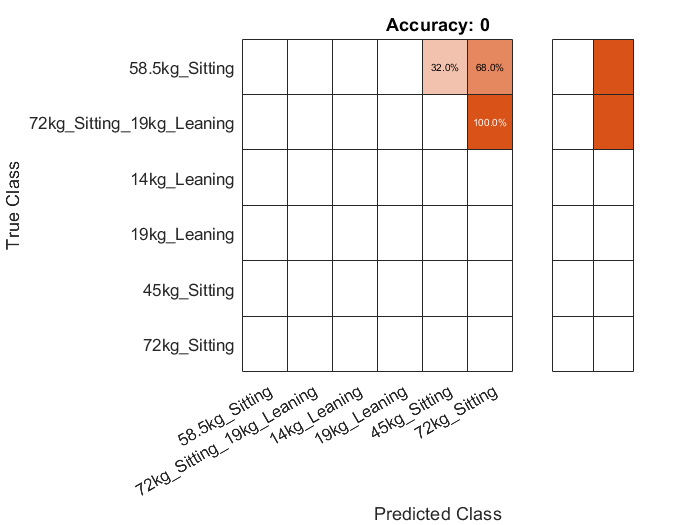

figure
c = confusionchart(yActual,yPred, "RowSummary", "row-normalized","Normalization","row-normalized");
title("Accuracy: "+string(accuracy))

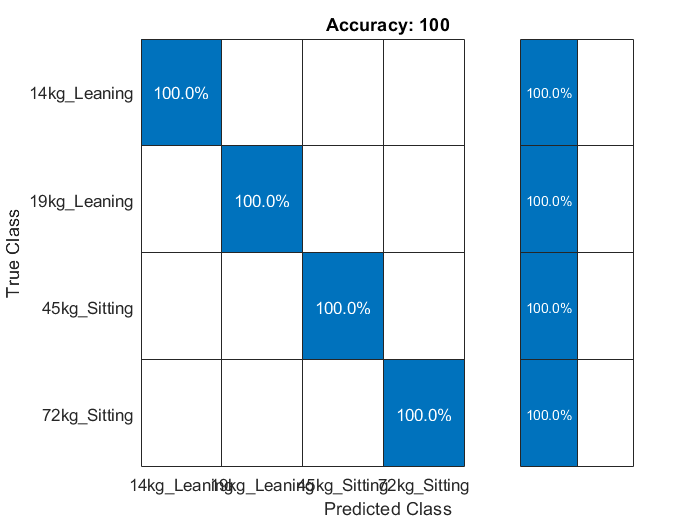

Error using xtickangle (line 30)
Using xtickangle with ConfusionMatrixChart is not supported.

figure
cTrain = confusionchart(yActualTrain,yPredTrain, "RowSummary", "row-normalized","Normalization","row-normalized");
title("Accuracy: "+string(accuracyTrain))